Irene Celestino - Daniele Poidomani 

23/11/2021

# Logbook

## Es. 1

Correnti Laser, modello LDM 808 3LJ: 

- massima 25 mA - soglia a 19 mA ;

- tensione massima che gli dai: 6 V (da 3 V in poi);

- Potenza: 3 mW;

- Lunghezza d'onda: 808 nm.

Montiamo il circuito:

 R1=150 Ohm (misura: 150.5 \pm 0.5 Ohm) : potenza massima dissipata è 150*(25 mA)^2 = 0.09 W e rimaniamo sotto 0.125 W, potenza massima della resistenza. Però usiamo quella (forse) da 0.5 W, per stare tranquilli. 

Manteniamo la tensione sotto 3 V per rimanere sotto i 20 mA (a 25 mA si avrebbe Vs=3,75, al massimo)

Messo il nero come catodo. 

Vmax = 6;
Pmax= 3e-3;
Imax = Pmax/Vmax

Imax =      5.000000000000000e-04


## Es. 2

Usiamo traccia V_I_DIFF per curva caratteristica corrente laser al variare di V: CB68-CB34

Spazzata:Vs tra 0.01 V e 3 V (così corrente massima è 20 mA)

Fondo scala: CB68 10 V  e CB34 5 V (è Vs, al max 3 V)

Prendiamo curva caratteristica con 50 misure 

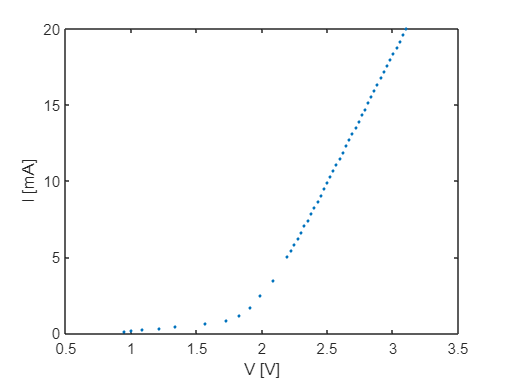

R=150;
datamat=readmatrix('Data LAB es 2');
V=datamat(:,1);
I=datamat(:,2)/R;
plot(V,I*1e3, '.')
xlabel('V [V]')
ylabel('I [mA]')

## Es. 3

h = 6.62607015e-34; %valore di CODATA atteso
e = 1.602176634e-19; %valore di CODATA atteso
c = 299792458;
Vt=1.54; %V
dVt=0.1; %V, presa ad occhio nel grafico, dove passa da lineare a emissione LED
E=e*Vt/c;
dE=e*dVt/c;
lambda=h/E

lambda =      8.050921976181835e-07


dlambda=h*dE/E^2

dlambda =      5.227871413105088e-08


## Es. 4

Scegliamo dimensioni circuito transimpedenza

Responsività = Corrente nel fotodiodo/potenza incidente = circa 0.45 a lambda 808 nm

potenza laser = 3 mW quindi corrente = 0.45*3mW viene 1.4 mA che scorre nel fotodiodo 

Vopamp=R*I quindi R=1 kOhm per avere Vopamp dell'ordine del V a potenza massima. Però non si arriva a potenza massima: mettiamo 10 kOhm 

Mettiamo fotodiodo con cavetto rosso (catodo) a terra, così corrente negativa (da -IN a terra)

## Es. 5

Testiamo cosa fa fotodiodo con illuminazione ambientale

Mettiamo 10 kOhm e luce ambientale segnaledi frequenza 100 Hz ampio 30 mV picco picco e centrato in -40 mV (quindi corrente dell'ordine di 30 mV/ 10kOhm = circa uA 

## Es. 6

Misura di CB33 (Vopamp) 

All'inizio con luce ambientale: dà noia, segnale del''ordine di luce ambientale 

Misura iniziale: rumore luce che filtra nel supporto, per capire offset luce a laser spento scollegato ('amb') 

Poi misura anche mettendo fotodiodo a luce ambiente ('full amb')

(in queste due non serve a niente corrente)

Mettiamo fotodiodo contro laser nel supporto e prendiamo curva Segnale Vopamp vs corrente nel laser. 

Impostazioni: 

- Vs tra 0.1 e 3 V 

- R = 150 Ohm 

- Fondo scala: CB68: 5 V e CB33: 0.5 V

Viene tipo una parabola 

IPD = Vopamp/Rtrans

Responsività = Corrente nel fotodiodo/potenza incidente

Potenza= IPD/Responsività = Vopamp /(Rtrans * responsività)

Vpeak=0.12; 
Rtrans= 10e3;
Resp=0.44; 
Pot_max=Vpeak/(Rtrans*Resp)

Pot_max =      2.727272727272727e-05


Abbiamo potenza massima di 27 uW

Decidiamo di alzare fino a 3.7 V Vin, per arrivare a correnti più vicine a 25 mA. Misura 'no fit' da 0.1 V a 3.7 V

Prendiamo misura con tanti punti per fare fit nella zona alta. Però OpAmp arriva fino a 23 mA e quindi ci fermiamo a Vs=3.45 V. 

Misura fit: da 2.7 V a 3.45 V in 100 misure 

Abbiamo scoperto il probkema: nel generatore corrente massima era impostata a 25 mA: lo alziamo a 30 mA

Nuova misura: fino a 3.7 V per arrivare a potenza massima (Vmax=1.7V) di 378 uW

Facciamo anche misura da 3.1 V a 3.75 V per il fit lineare. ('FIT FIT')

Pot_max=2.1/(Rtrans*Resp)

Pot_max =      4.772727272727273e-04


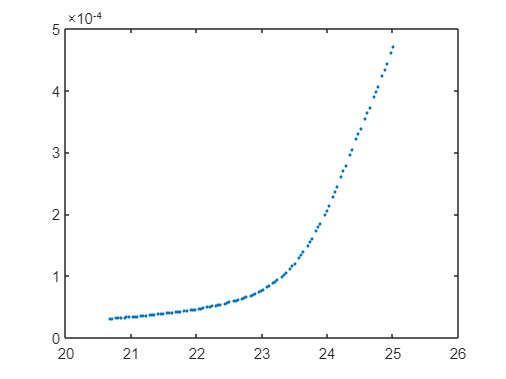

datamat=readmatrix('Data LAB es 6 fit fit');
Ilaser=datamat(:,1);
Vopamp=datamat(:,2);
Vopamp=Vopamp*(-1);

plot(Ilaser, Vopamp/(Rtrans*Resp), '.')

0.4/(Rtrans*Resp)

ans =      9.090909090909092e-05


I_100=3.4/150

I_100 =    0.022666666666667


## Es. 8 

Misura potenza con sensore: 

Vs=2.000 pm 0.001  15 uW

Vs=2.5  30 uW

Vs=3 Pot50 uW 

Vs=3.5 138 uW 

Vs= 3.4 100 uW 

Vs=3.75 700 uW 

Vs= 4  viene ordine mW

Non sono compatibili con le nostre misure. Ne prendiamo un'altra mettendo a contatto laser e fotodiodo 

## Es. 9

Scegliamo potenza di 100 uW: 

Fattore tensione potenza: 

Potenza=  Vopamp /(Rtrans * responsività) cioè fattore = 228 uW/V 

1/(0.44*10e3)

ans =      2.272727272727273e-04


## Es. 11

Cuvette vuota

Riprendiamo misura senza cuvette con posizione laser per cui c'entra la cuvette  ("quello buono")

V = potenza*R*resp 

100e-6*10e3*0.45

ans =    0.450000000000000


A 100 uW serve tensione 0.45 V 

Nella nostra curva Vopamp 0.45 V a 23.4 mA pm 0.1 

Vs= 3.51 V

150*23.4e-3

ans =    3.510000000000000


dI=0.02/150

dI =      1.333333333333333e-04


Usiamo Vin_Vout2C.vi , impostiamo Vs a 3.5110 pm 0.0008 V

- senza cuvette: Vopamp = -0.440  pm 0.02 V (appena acceso, poi o sale o scende di anche 0.05) 

- con cuvette: (la mettiamo varie volte sempre più o meno in stessa posizione) 0.389 - 0.390 - 0.388 - 0.391 V - 0.389

- Errore per spostamento cuvette: 0.02 V

- Senza laser, col buio: -0.00158 pm 0.0003 V

Attenuazione_uW = (0.455-0.385)/(10e3*0.45)

Attenuazione_uW =      1.555555555555556e-05


## Es. 12

Concentrazioni: (misura con 0.5 V fs o 0.05 per le concentrazioni più alte)

1 : 0.01 M : Vopamp = 0.261 - 0.262 - 0.263 - 0.261 V

2: 0.05 M : Vopamp = 0.0683 - 0.0693 pm 0.0004 - 0.0699 - 00.6984

3: 0.1 M : Vopamp = 0.0316 - 0.0316 - 0.0317 

4. 0.25 M : (pm 0.0003)

5. 0.5 M:

6. 1 M :

V0=0.440;
dV0=0.02

dV0 =    0.020000000000000


V1_array=[0.261  0.262  0.263  0.261];
V_op(1)=mean(V1_array)+0.0004;;
dV_op(1)=std(V1_array)+0.0004;;
V2_array=[ 0.0683  0.0693 0.0699  0.06984];
V_op(2)=mean(V2_array);
dV_op(2)=std(V2_array)+0.0004;;
V3_array=[ 0.0316  0.0316  0.0317 ];
V_op(3)=mean(V3_array);
dV_op(3)=std(V3_array)+0.0004;
V4_array=[-0.0019]

V4_array =   -0.001900000000000


dV_op(4)=0.0003;

V_op(4)=mean(V4_array);
V5_array=[-0.00270]

V5_array =   -0.002700000000000


dV_op(5)=0.0003;
V_op(5)=mean(V5_array);
V6_array=[-0.00270]

V6_array =   -0.002700000000000


V_op(6)=mean(V6_array);
dV_op(6)=0.0003;


c=[ 0.01, 0.05, 0.1, 0.25, 0.5, 1]; %M


I0=V0/(10e3*0.45);
I=V_op/(10e3*0.45);
dI=dV_op/(10e3*0.45);
V_op=V_op+0.00270

V_op =     0.2649    0.0720    0.0343    0.0008         0         0


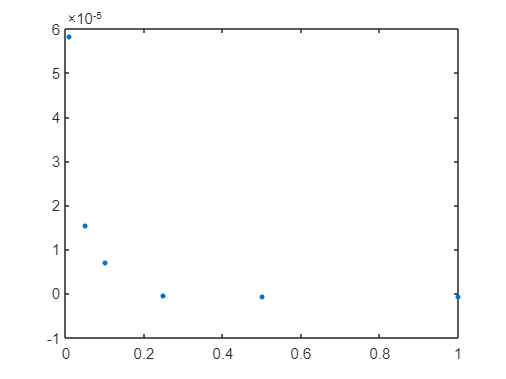

plot(c, I,'.', 'MarkerSize',10)